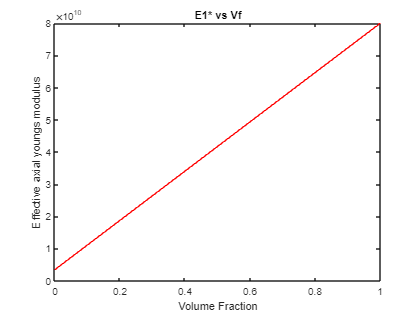

% STRENGTH OF MATERIALS APPROACH %
clear all;
format long e
% GIVEN QUANTITIES
E1_f = 80000000000;
E2_f = 80000000000;
G12_f = 33330000000;
E_m =  3350000000;
nu_m = 0.35;
G_m = E_m/((1+nu_m)*2);
nu12_f = 0.2;
alpha1_f = 4.9*10^-6;
alpha2_f = 4.9*10^-6;
alpha_m = 58*10^-6;
% Vf = 0.5


% SOME USEFUL QUANTITIES AND DEFINITIONS
t = linspace(0,1,100);
syms Vf
Vm = 1-Vf;

% EFFECTIVE AXIAL YOUNGS MODULUS
E1star = E1_f*Vf + E_m*(1-Vf);
E1star = double(subs(E1star,Vf,t));
plot(t,E1star,'r','Linewidth',0.2);
title("E1* vs Vf")
xlabel("Volume Fraction")
ylabel("Effective axial youngs modulus")

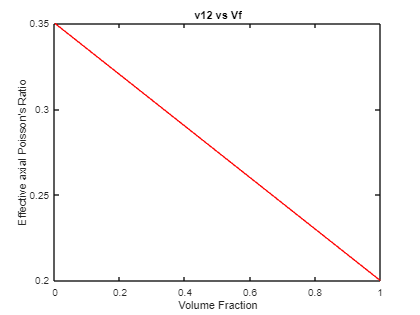


% EFFECTIVE AXIAL POISSON'S RATIO
nu12star = nu12_f*Vf + nu_m*(1-Vf);
nu12star = double(subs(nu12star,Vf,t));
plot(t,nu12star,'r','Linewidth',0.2);
title("v12 vs Vf")
xlabel("Volume Fraction")
ylabel("Effective axial Poisson's Ratio")

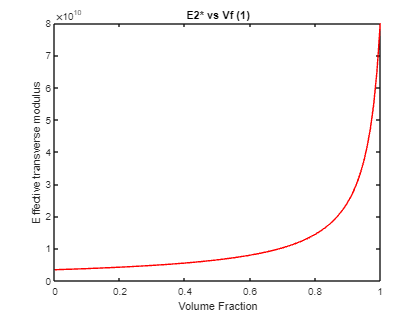


% EFFECTIVE TRANSVERSE MODULUS
% 1. when deformation in direction 1 is not considered
E2star = 1/((Vf/E2_f)+((1-Vf)/E_m));
E2star = double(subs(E2star,Vf,t));
plot(t,E2star,'r','Linewidth',0.2);
title("E2* vs Vf (1)")
xlabel("Volume Fraction")
ylabel("Effective transverse modulus")

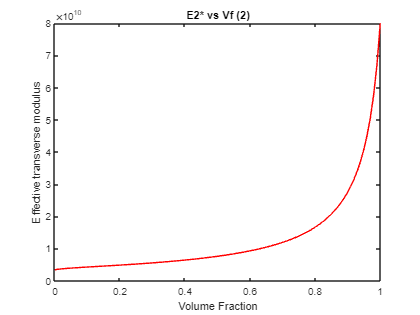

% 2. when deformation in direction 1 is also considered
eta_f = (E1_f*Vf+((1-nu12_f*nu12_f)*E_m+nu_m*nu12_f*E1_f)*(1-Vf))/(E1_f*Vf+E_m*(1-Vf));
eta_m = (E_m*Vm+((1-nu_m*nu_m)*E1_f-(1-nu_m*nu12_f)*E_m)*Vf)/(E1_f*Vf+E_m*(1-Vf));
E2star = 1/((eta_f*Vf/E2_f)+(eta_m*(1-Vf)/E_m));
E2star = double(subs(E2star,Vf,t));
plot(t,E2star,'r','Linewidth',0.2);
title("E2* vs Vf (2)")
xlabel("Volume Fraction")
ylabel("Effective transverse modulus")

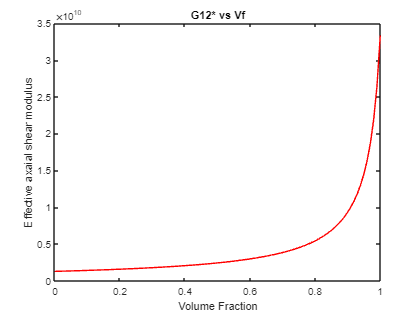


% EFFECTIVE AXIAL SHEAR MODULUS
G12star = 1/((Vf/G12_f)+((1-Vf)/G_m));
G12star = double(subs(G12star,Vf,t));
plot(t,G12star,'r','Linewidth',0.2);
title("G12* vs Vf")
xlabel("Volume Fraction")
ylabel("Effective axaial shear modulus")

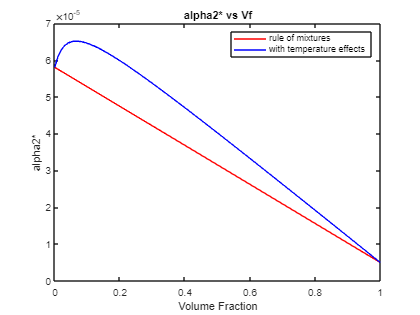


% COEFFICIENT OF THERMAL EXPANSION
% 1.coefficients of thermal expansion in transverse direction, alpha2*
alpha2_star = alpha2_f*Vf + alpha_m*(1-Vf);
alpha2_star = double(subs(alpha2_star,Vf,t));
plot(t,alpha2_star,'r','Linewidth',0.2);
title("alpha2* vs Vf")
xlabel("Volume Fraction")
ylabel("alpha2*")
hold on
% 2. Alternative approach for alpha2*
alpha2_star = alpha2_f*Vf+alpha_m*Vm+((nu_m*E1_f-nu12_f*E_m)/(E1_f*Vf + E_m*(1-Vf)))*(alpha_m-alpha1_f)*(1-Vf)*Vf;
alpha2_star = double(subs(alpha2_star,Vf,t));
plot(t,alpha2_star,'b','Linewidth',0.2);
%title("alpha2* vs Vf")
% xlabel("Volume Fraction")
% ylabel("alpha2*")
hold off
legend(["rule of mixtures","with temperature effects"])

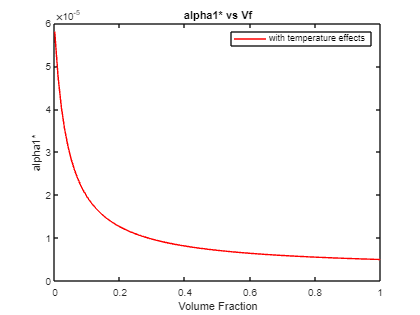


% 2. Alternative approach for alpha1*
alpha1_star = ((alpha1_f*E1_f-alpha_m*E_m)*Vf+alpha_m*E_m)/((E1_f-E_m)*Vf+ E_m);
alpha1_star = double(subs(alpha1_star,Vf,t));
plot(t,alpha1_star,'r','Linewidth',0.2);
title("alpha1* vs Vf")
xlabel("Volume Fraction")
ylabel("alpha1*")
legend("with temperature effects")